## **LAB1 第一章 周期信号的傅里叶级数表示**

#### 应逸雯12210159 陈薇羽12210460

### 通过本实验的练习，掌握了以下技能：

1.通过y./x辨别特征函数

2.使用for循环计算傅里叶级数

3.使用fft、ifft、fftshift等快速傅里叶级数计算工具

### 作业内容

#### 3.5a a0=1,a2=a2*=exp(1i*pi/4),a4=a-4*=2*exp(1i*pi/3)。判断x[n]是复数/实数/纯虚数。

由于ak=a-k*，傅里叶级数共轭相等，故x[n]是实数。

#### 3.5b 创建向量a。

条件隐含a1=a-4，a3=a-2。注意元素索引需+1

clc,clear,close all;
a=zeros(1,5);
a(1)=1;
a(2)=2*exp(-1i*pi/3);
a(3)=exp(1i*pi/4);
a(4)=exp(-1i*pi/4);
a(5)=2*exp(1i*pi/3);
a

a =    1.0000 + 0.0000i   1.0000 - 1.7321i   0.7071 + 0.7071i   0.7071 - 0.7071i   1.0000 + 1.7321i


#### 3.5c 计算出x[n]，并画图，并于3.5a的结论相比较。

用for循环带入合成公式计算，若仅有舍入误差，则为纯实数信号。

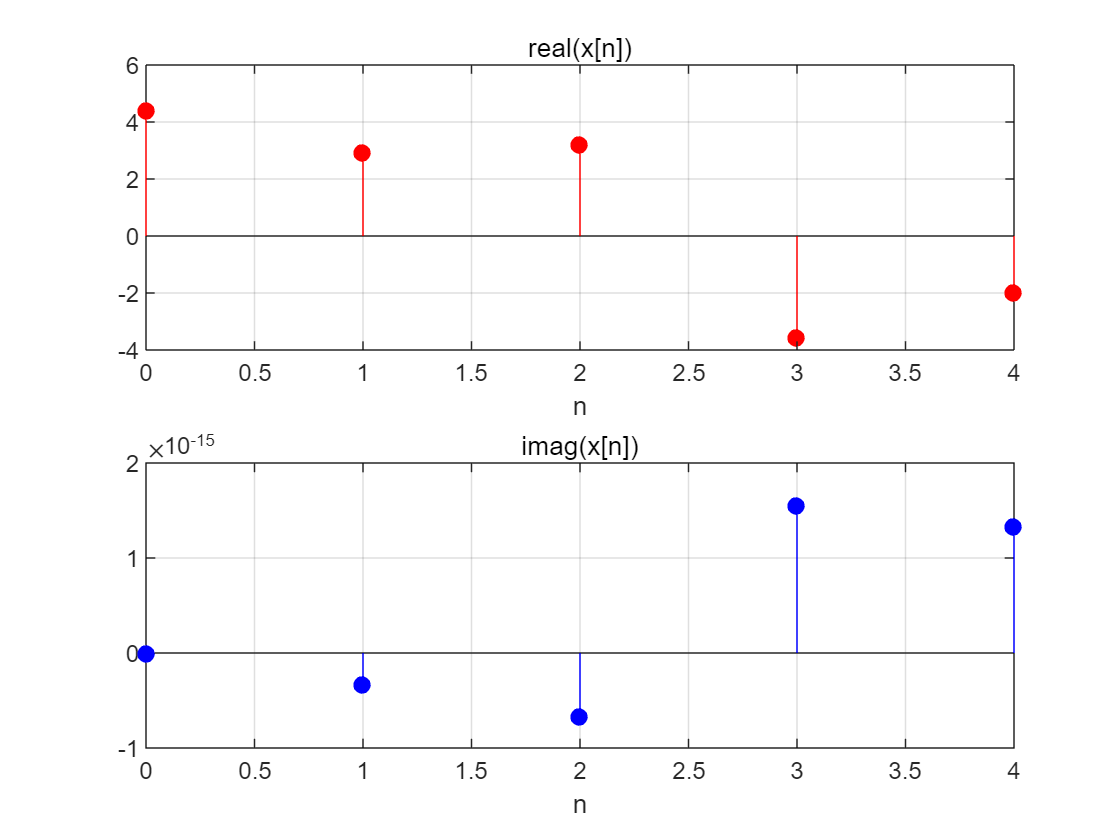

x=[];
nx=0:4;
N=5;
for u=0:4%u为x的索引值
    temp=0;
    for v=0:4%用于求和
        temp=temp+a(v+1)*exp(1i*v*2*pi/N*u);
    end
    x=[x temp];
end
%得到了x[n]
figure;
subplot(2,1,1),stem(nx,real(x),'r','filled'),title('real(x[n])'),xlabel('n'),grid on;
subplot(2,1,2),stem(nx,imag(x),'b','filled'),title('imag(x[n])'),xlabel('n'),grid on;

根据x[n]的实部和虚部的图像，虚部误差量级为10^-15，属于舍入误差，在可接受范围内，可得知，x[n]是纯实数信号。

#### 3.5d 定义x1=ones(1,8)(0<=n<=7)，x2=[ones(1,8) zeros(1,8)](0<=n<=15)，x3=[ones(1,8) zeros(1,24)](0<=n=31)，并且绘制[0,63]区间的图像。

先给x1，x2，x3赋值，绘图时拼接多个周期。

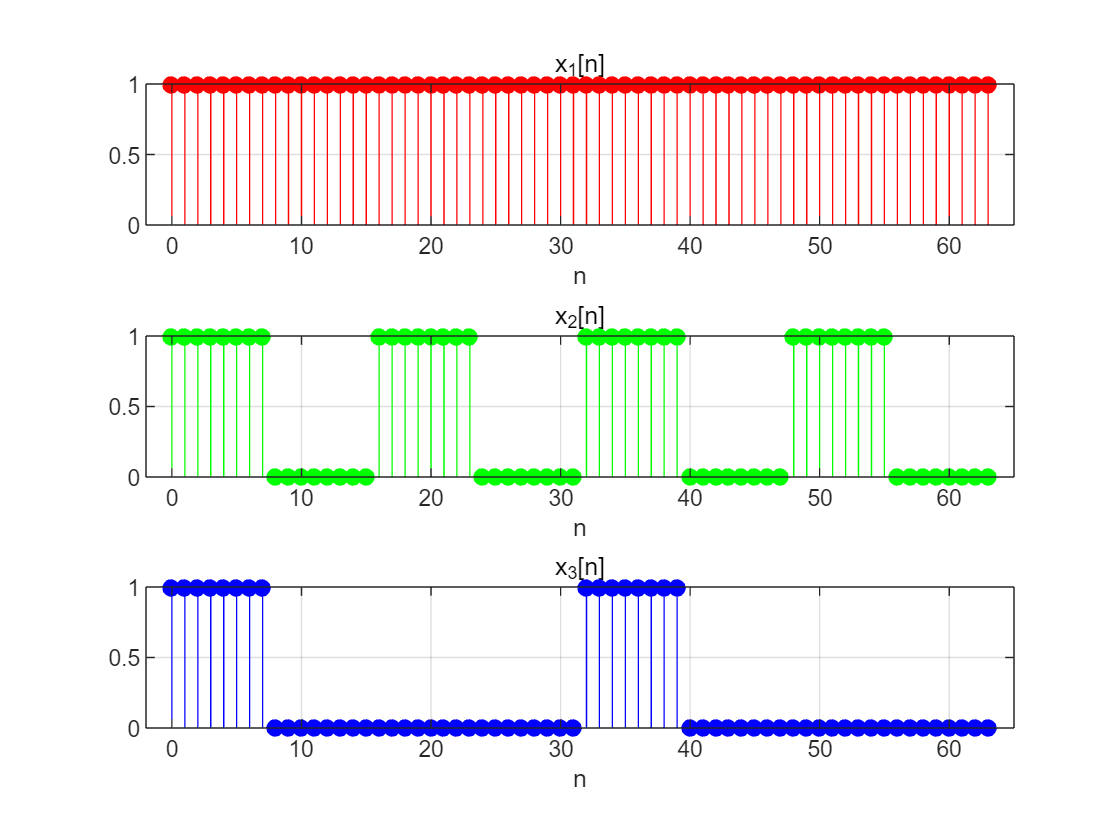

clc,clear,close all;
nx1=0:7;
x1=ones(1,8);
nx2=0:15;
x2=[ones(1,8) zeros(1,8)];
nx3=0:31;
x3=[ones(1,8) zeros(1,24)];
nx=0:63;
%创建好了x1,x2,x3
figure;
subplot(3,1,1),stem(nx,[x1 x1 x1 x1 x1 x1 x1 x1],'r','filled'),title('x_1[n]'),xlabel('n'),grid on,xlim([-2 65]);
subplot(3,1,2),stem(nx,[x2 x2 x2 x2],'g','filled'),title('x_2[n]'),xlabel('n'),grid on,xlim([-2 65]);
subplot(3,1,3),stem(nx,[x3 x3],'b','filled'),title('x_3[n]'),xlabel('n'),grid on,xlim([-2 65]);

结果如图。

#### 3.5e 用fft计算a1，a2，a3，并画出绝对值图像。预测a1(1)，a2(1)，a3(1)，并与图像相比较。

计算a1，a2，a3使用a=fft(x)/N公式。

a(1)=sum(x[n])/N，故a1(1)=1，a2(1)=0.5，a3(1)=0.25。

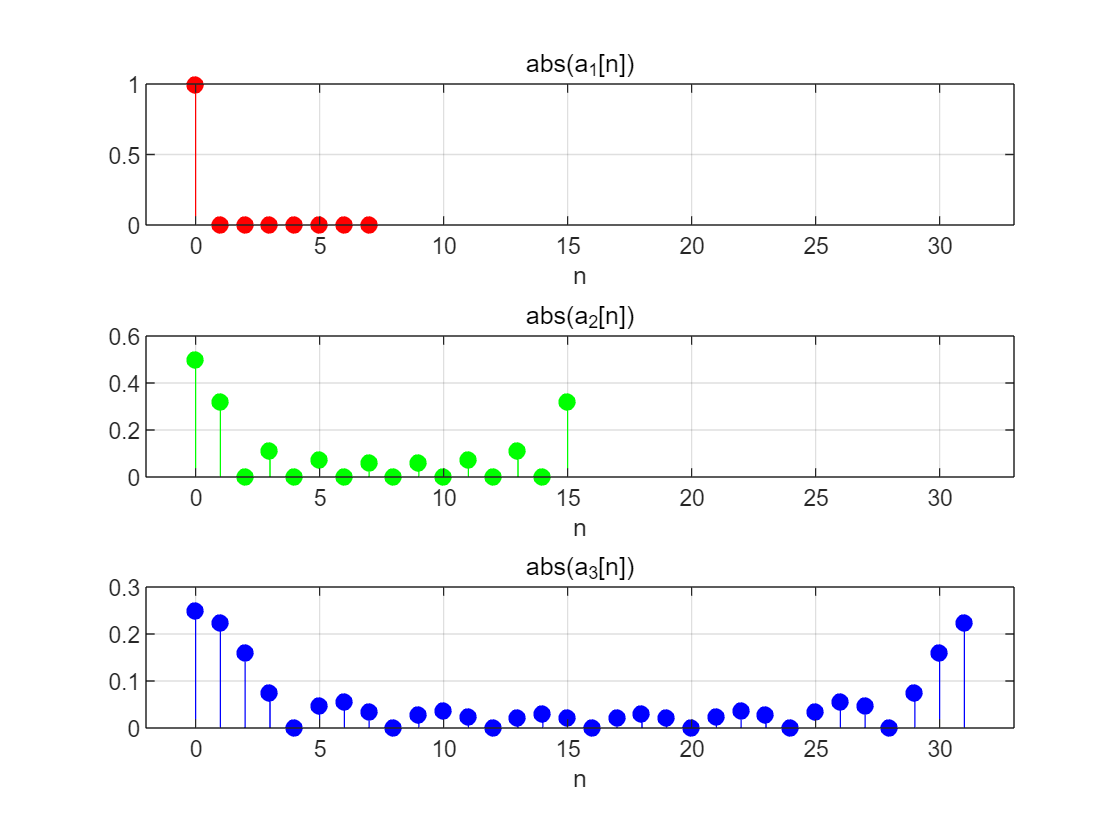

N1=8;
N2=16;
N3=32;
a1=fft(x1)/N1;
a2=fft(x2)/N2;
a3=fft(x3)/N3;
%计算出了a1,a2,a3
figure;
subplot(3,1,1),stem(nx1,abs(a1),'r','filled'),title('abs(a_1[n])'),xlabel('n'),grid on,xlim([-2 33]);
subplot(3,1,2),stem(nx2,abs(a2),'g','filled'),title('abs(a_2[n])'),xlabel('n'),grid on,xlim([-2 33]);
subplot(3,1,3),stem(nx3,abs(a3),'b','filled'),title('abs(a_3[n])'),xlabel('n'),grid on,xlim([-2 33]);

根据图像，a1(1)，a2(1)，a3(1)与理论值相同。

#### 3.5f 观察仅使用部分a，计算出x3-2，x3-8，x3-12，x3-all

用for循环计算x，需调整v部分参数，并且分开求正数索引和负数索引，最后画图。

nx=0:31;
N=32;
x3_2=[];
for u=0:31%u为x的索引值
    temp=0;
    for v=0:2%求正数索引部分
        temp=temp+a3(v+1)*exp(1i*v*2*pi/N*u);
    end
    for w=-2:-1%求负数索引部分
        temp=temp+conj(a3(1-w))*exp(1i*w*2*pi/N*u);
    end
    x3_2=[x3_2 temp];
end
x3_2

x3_2 =    0.6610 + 0.0000i   0.8256 + 0.0000i   0.9478 - 0.0000i   1.0129 + 0.0000i   1.0129 - 0.0000i   0.9478 + 0.0000i   0.8256 + 0.0000i   0.6610 + 0.0000i   0.4735 + 0.0000i   0.2846 - 0.0000i   0.1145 + 0.0000i  -0.0200 + 0.0000i  -0.1084 + 0.0000i  -0.1473 + 0.0000i  -0.1405 + 0.0000i  -0.0985 + 0.0000i  -0.0360 + 0.0000i   0.0303 + 0.0000i   0.0849 + 0.0000i   0.1155 + 0.0000i   0.1155 + 0.0000i   0.0849 + 0.0000i   0.0303 + 0.0000i  -0.0360 + 0.0000i  -0.0985 + 0.0000i  -0.1405 + 0.0000i  -0.1473 + 0.0000i  -0.1084 + 0.0000i  -0.0200 + 0.0000i   0.1145 + 0.0000i   0.2846 + 0.0000i   0.4735 + 0.0000i


%得到了x3_2[n]
x3_8=[];
for u=0:31%u为x的索引值
    temp=0;
    for v=0:8%求正数索引部分
        temp=temp+a3(v+1)*exp(1i*v*2*pi/N*u);
    end
    for w=-8:-1%求负数索引部分
        temp=temp+conj(a3(1-w))*exp(1i*w*2*pi/N*u);
    end
    x3_8=[x3_8 temp];
end
x3_8

x3_8 =    0.7347 + 0.0000i   1.0900 + 0.0000i   1.0900 - 0.0000i   0.9285 + 0.0000i   0.9285 - 0.0000i   1.0900 + 0.0000i   1.0900 + 0.0000i   0.7347 + 0.0000i   0.2347 + 0.0000i  -0.0570 + 0.0000i  -0.0570 + 0.0000i   0.0293 + 0.0000i   0.0293 + 0.0000i  -0.0197 + 0.0000i  -0.0197 + 0.0000i   0.0153 + 0.0000i   0.0153 + 0.0000i  -0.0134 + 0.0000i  -0.0134 + 0.0000i   0.0128 + 0.0000i   0.0128 + 0.0000i  -0.0134 + 0.0000i  -0.0134 + 0.0000i   0.0153 + 0.0000i   0.0153 + 0.0000i  -0.0197 + 0.0000i  -0.0197 + 0.0000i   0.0293 + 0.0000i   0.0293 + 0.0000i  -0.0570 + 0.0000i  -0.0570 + 0.0000i   0.2347 - 0.0000i


%得到了x3_8[n]
x3_12=[];
for u=0:31%u为x的索引值
    temp=0;
    for v=0:12%求正数索引部分
        temp=temp+a3(v+1)*exp(1i*v*2*pi/N*u);
    end
    for w=-12:-1%求负数索引部分
        temp=temp+conj(a3(1-w))*exp(1i*w*2*pi/N*u);
    end
    x3_12=[x3_12 temp];
end
x3_12

x3_12 =    0.8686 + 0.0000i   1.1199 + 0.0000i   0.9160 - 0.0000i   1.0302 - 0.0000i   1.0302 - 0.0000i   0.9160 + 0.0000i   1.1199 + 0.0000i   0.8686 + 0.0000i   0.1186 + 0.0000i  -0.0876 + 0.0000i   0.0486 + 0.0000i  -0.0124 + 0.0000i  -0.0124 + 0.0000i   0.0222 + 0.0000i  -0.0183 + 0.0000i   0.0064 + 0.0000i   0.0064 + 0.0000i  -0.0139 + 0.0000i   0.0132 + 0.0000i  -0.0053 + 0.0000i  -0.0053 + 0.0000i   0.0132 + 0.0000i  -0.0139 + 0.0000i   0.0064 + 0.0000i   0.0064 + 0.0000i  -0.0183 + 0.0000i   0.0222 + 0.0000i  -0.0124 + 0.0000i  -0.0124 + 0.0000i   0.0486 + 0.0000i  -0.0876 + 0.0000i   0.1186 - 0.0000i


%得到了x3_12[n]
x3_all=[];
for u=0:31%u为x的索引值
    temp=0;
    for v=0:16%求正数索引部分
        temp=temp+a3(v+1)*exp(1i*v*2*pi/N*u);
    end
    for w=-15:-1
        temp=temp+conj(a3(1-w))*exp(1i*w*2*pi/N*u);
    end
    x3_all=[x3_all temp];
end
x3_all

x3_all =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 - 0.0000i   1.0000 - 0.0000i   1.0000 - 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i


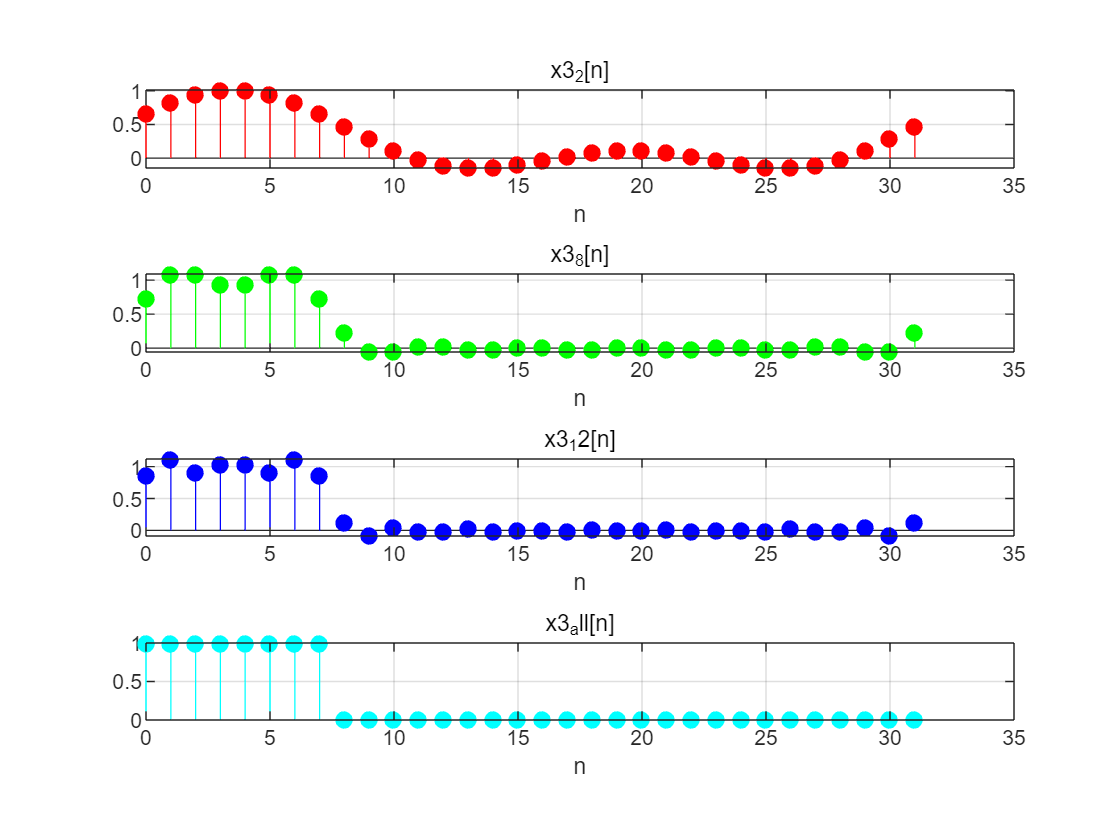

%得到了x3_all[n]
figure;
subplot(4,1,1),stem(nx,real(x3_2),'r','filled'),title('x3_2[n]'),xlabel('n'),grid on;
subplot(4,1,2),stem(nx,real(x3_8),'g','filled'),title('x3_8[n]'),xlabel('n'),grid on;
subplot(4,1,3),stem(nx,real(x3_12),'b','filled'),title('x3_12[n]'),xlabel('n'),grid on;
subplot(4,1,4),stem(nx,real(x3_all),'c','filled'),title('x3_all[n]'),xlabel('n'),grid on;

可观察到，当使用的谐波数量越多，越能够还原信号。

#### 3.5g 证明x3_all[n]一定为纯实数信号。

画出x3_all虚部，如果仅有舍入误差，则为纯实数信号。

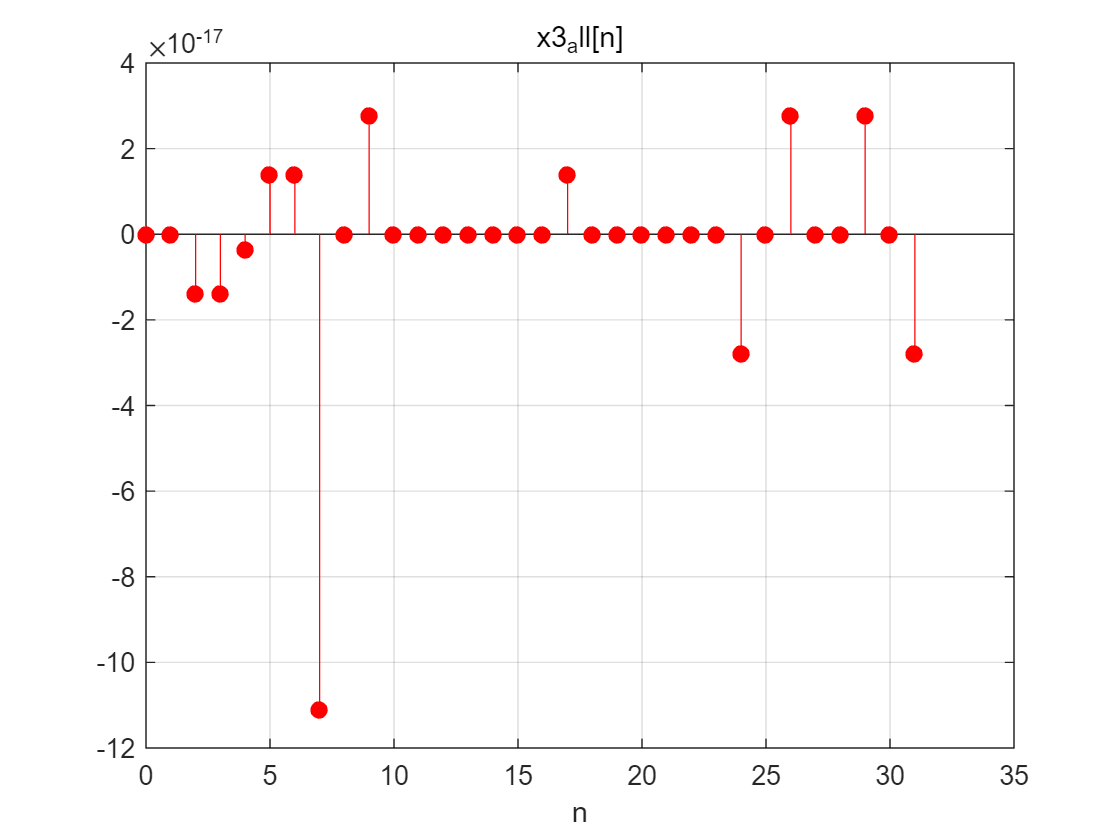

figure;
stem(nx,imag(x3_all),'r','filled'),title('x3_all[n]'),xlabel('n'),grid on;

误差量级为10^-17，考虑到舍入误差，在可接受范围内，故x3_all[n]为纯实数信号。

x3_all是从a3变换坐标计算而来，而间隔一个周期变换坐标不影响还原信号，a3又是由x3原信号计算得出，故x3_all理应与x3相同。

#### 3.5h 观察更多的谐波数量是否能够更加还原信号。并且观察是否有吉布斯现象。

nx=0:31;
N=32;

x3_1=[];
for u=0:31%u为x的索引值
    temp=0;
    for v=0:1%求正数索引部分
        temp=temp+a3(v+1)*exp(1i*v*2*pi/N*u);
    end
    w=-1;%求负数索引部分
    temp=temp+conj(a3(1-w))*exp(1i*w*2*pi/N*u);
    x3_1=[x3_1 temp];
end
x3_1

x3_1 =     0.5985    0.6476    0.6815    0.6987    0.6987    0.6815    0.6476    0.5985    0.5360    0.4625    0.3809    0.2942    0.2058    0.1191    0.0375   -0.0360   -0.0985   -0.1476   -0.1815   -0.1987   -0.1987   -0.1815   -0.1476   -0.0985   -0.0360    0.0375    0.1191    0.2058    0.2942    0.3809    0.4625    0.5360


%得到了x3_1[n]

x3_2=[];
for u=0:31%u为x的索引值
    temp=0;
    for v=0:2%求正数索引部分
        temp=temp+a3(v+1)*exp(1i*v*2*pi/N*u);
    end
    for w=-2:-1%求负数索引部分
        temp=temp+conj(a3(1-w))*exp(1i*w*2*pi/N*u);
    end
    x3_2=[x3_2 temp];
end
x3_2

x3_2 =    0.6610 + 0.0000i   0.8256 + 0.0000i   0.9478 - 0.0000i   1.0129 + 0.0000i   1.0129 - 0.0000i   0.9478 + 0.0000i   0.8256 + 0.0000i   0.6610 + 0.0000i   0.4735 + 0.0000i   0.2846 - 0.0000i   0.1145 + 0.0000i  -0.0200 + 0.0000i  -0.1084 + 0.0000i  -0.1473 + 0.0000i  -0.1405 + 0.0000i  -0.0985 + 0.0000i  -0.0360 + 0.0000i   0.0303 + 0.0000i   0.0849 + 0.0000i   0.1155 + 0.0000i   0.1155 + 0.0000i   0.0849 + 0.0000i   0.0303 + 0.0000i  -0.0360 + 0.0000i  -0.0985 + 0.0000i  -0.1405 + 0.0000i  -0.1473 + 0.0000i  -0.1084 + 0.0000i  -0.0200 + 0.0000i   0.1145 + 0.0000i   0.2846 + 0.0000i   0.4735 + 0.0000i


%得到了x3_2[n]

x3_3=[];
for u=0:31%u为x的索引值
    temp=0;
    for v=0:3%求正数索引部分
        temp=temp+a3(v+1)*exp(1i*v*2*pi/N*u);
    end
    for w=-3:-1%求负数索引部分
        temp=temp+conj(a3(1-w))*exp(1i*w*2*pi/N*u);
    end
    x3_3=[x3_3 temp];
end
x3_3

x3_3 =    0.5893 + 0.0000i   0.8405 + 0.0000i   1.0444 - 0.0000i   1.1586 + 0.0000i   1.1586 - 0.0000i   1.0444 + 0.0000i   0.8405 + 0.0000i   0.5893 + 0.0000i   0.3393 + 0.0000i   0.1330 - 0.0000i  -0.0032 + 0.0000i  -0.0642 + 0.0000i  -0.0642 + 0.0000i  -0.0296 + 0.0000i   0.0110 + 0.0000i   0.0357 + 0.0000i   0.0357 + 0.0000i   0.0154 + 0.0000i  -0.0117 + 0.0000i  -0.0302 + 0.0000i  -0.0302 + 0.0000i  -0.0117 + 0.0000i   0.0154 + 0.0000i   0.0357 + 0.0000i   0.0357 + 0.0000i   0.0110 + 0.0000i  -0.0296 + 0.0000i  -0.0642 + 0.0000i  -0.0642 + 0.0000i  -0.0032 + 0.0000i   0.1330 + 0.0000i   0.3393 + 0.0000i


%得到了x3_3[n]

x3_4=[];
for u=0:31%u为x的索引值
    temp=0;
    for v=0:4%求正数索引部分
        temp=temp+a3(v+1)*exp(1i*v*2*pi/N*u);
    end
    for w=-4:-1%求负数索引部分
        temp=temp+conj(a3(1-w))*exp(1i*w*2*pi/N*u);
    end
    x3_4=[x3_4 temp];
end
x3_4

x3_4 =    0.5893 + 0.0000i   0.8405 + 0.0000i   1.0444 - 0.0000i   1.1586 + 0.0000i   1.1586 - 0.0000i   1.0444 + 0.0000i   0.8405 + 0.0000i   0.5893 + 0.0000i   0.3393 + 0.0000i   0.1330 - 0.0000i  -0.0032 + 0.0000i  -0.0642 + 0.0000i  -0.0642 + 0.0000i  -0.0296 + 0.0000i   0.0110 + 0.0000i   0.0357 + 0.0000i   0.0357 + 0.0000i   0.0154 + 0.0000i  -0.0117 + 0.0000i  -0.0302 + 0.0000i  -0.0302 + 0.0000i  -0.0117 + 0.0000i   0.0154 + 0.0000i   0.0357 + 0.0000i   0.0357 + 0.0000i   0.0110 + 0.0000i  -0.0296 + 0.0000i  -0.0642 + 0.0000i  -0.0642 + 0.0000i  -0.0032 + 0.0000i   0.1330 + 0.0000i   0.3393 + 0.0000i


%得到了x3_4[n]

x3_5=[];
for u=0:31%u为x的索引值
    temp=0;
    for v=0:5%求正数索引部分
        temp=temp+a3(v+1)*exp(1i*v*2*pi/N*u);
    end
    for w=-5:-1%求负数索引部分
        temp=temp+conj(a3(1-w))*exp(1i*w*2*pi/N*u);
    end
    x3_5=[x3_5 temp];
end
x3_5

x3_5 =    0.6790 + 0.0000i   0.9130 + 0.0000i   1.0352 - 0.0000i   1.0759 + 0.0000i   1.0759 - 0.0000i   1.0352 + 0.0000i   0.9130 + 0.0000i   0.6790 + 0.0000i   0.3665 + 0.0000i   0.0736 + 0.0000i  -0.0965 + 0.0000i  -0.1084 + 0.0000i  -0.0200 + 0.0000i   0.0637 + 0.0000i   0.0705 + 0.0000i   0.0085 + 0.0000i  -0.0540 + 0.0000i  -0.0571 + 0.0000i  -0.0025 + 0.0000i   0.0525 + 0.0000i   0.0525 + 0.0000i  -0.0025 + 0.0000i  -0.0571 + 0.0000i  -0.0540 + 0.0000i   0.0085 + 0.0000i   0.0705 + 0.0000i   0.0637 + 0.0000i  -0.0200 + 0.0000i  -0.1084 + 0.0000i  -0.0965 + 0.0000i   0.0736 + 0.0000i   0.3665 - 0.0000i


%得到了x3_5[n]

x3_6=[];
for u=0:31%u为x的索引值
    temp=0;
    for v=0:6%求正数索引部分
        temp=temp+a3(v+1)*exp(1i*v*2*pi/N*u);
    end
    for w=-6:-1%求负数索引部分
        temp=temp+conj(a3(1-w))*exp(1i*w*2*pi/N*u);
    end
    x3_6=[x3_6 temp];
end
x3_6

x3_6 =    0.7415 + 0.0000i   1.0234 + 0.0000i   1.0572 - 0.0000i   0.9824 + 0.0000i   0.9824 - 0.0000i   1.0572 + 0.0000i   1.0234 + 0.0000i   0.7415 + 0.0000i   0.3040 + 0.0000i  -0.0368 + 0.0000i  -0.1184 + 0.0000i  -0.0149 + 0.0000i   0.0735 + 0.0000i   0.0418 + 0.0000i  -0.0399 + 0.0000i  -0.0540 + 0.0000i   0.0085 + 0.0000i   0.0533 + 0.0000i   0.0195 + 0.0000i  -0.0410 + 0.0000i  -0.0410 + 0.0000i   0.0195 + 0.0000i   0.0533 + 0.0000i   0.0085 + 0.0000i  -0.0540 + 0.0000i  -0.0399 + 0.0000i   0.0418 + 0.0000i   0.0735 + 0.0000i  -0.0149 + 0.0000i  -0.1184 + 0.0000i  -0.0368 + 0.0000i   0.3040 - 0.0000i


%得到了x3_6[n]

x3_7=[];
for u=0:31%u为x的索引值
    temp=0;
    for v=0:7%求正数索引部分
        temp=temp+a3(v+1)*exp(1i*v*2*pi/N*u);
    end
    for w=-7:-1%求负数索引部分
        temp=temp+conj(a3(1-w))*exp(1i*w*2*pi/N*u);
    end
    x3_7=[x3_7 temp];
end
x3_7

x3_7 =    0.7347 + 0.0000i   1.0900 + 0.0000i   1.0900 - 0.0000i   0.9285 + 0.0000i   0.9285 - 0.0000i   1.0900 + 0.0000i   1.0900 + 0.0000i   0.7347 + 0.0000i   0.2347 + 0.0000i  -0.0570 + 0.0000i  -0.0570 + 0.0000i   0.0293 + 0.0000i   0.0293 + 0.0000i  -0.0197 + 0.0000i  -0.0197 + 0.0000i   0.0153 + 0.0000i   0.0153 + 0.0000i  -0.0134 + 0.0000i  -0.0134 + 0.0000i   0.0128 + 0.0000i   0.0128 + 0.0000i  -0.0134 + 0.0000i  -0.0134 + 0.0000i   0.0153 + 0.0000i   0.0153 + 0.0000i  -0.0197 + 0.0000i  -0.0197 + 0.0000i   0.0293 + 0.0000i   0.0293 + 0.0000i  -0.0570 + 0.0000i  -0.0570 + 0.0000i   0.2347 - 0.0000i


%得到了x3_7[n]

x3_8=[];
for u=0:31%u为x的索引值
    temp=0;
    for v=0:8%求正数索引部分
        temp=temp+a3(v+1)*exp(1i*v*2*pi/N*u);
    end
    for w=-8:-1%求负数索引部分
        temp=temp+conj(a3(1-w))*exp(1i*w*2*pi/N*u);
    end
    x3_8=[x3_8 temp];
end
x3_8

x3_8 =    0.7347 + 0.0000i   1.0900 + 0.0000i   1.0900 - 0.0000i   0.9285 + 0.0000i   0.9285 - 0.0000i   1.0900 + 0.0000i   1.0900 + 0.0000i   0.7347 + 0.0000i   0.2347 + 0.0000i  -0.0570 + 0.0000i  -0.0570 + 0.0000i   0.0293 + 0.0000i   0.0293 + 0.0000i  -0.0197 + 0.0000i  -0.0197 + 0.0000i   0.0153 + 0.0000i   0.0153 + 0.0000i  -0.0134 + 0.0000i  -0.0134 + 0.0000i   0.0128 + 0.0000i   0.0128 + 0.0000i  -0.0134 + 0.0000i  -0.0134 + 0.0000i   0.0153 + 0.0000i   0.0153 + 0.0000i  -0.0197 + 0.0000i  -0.0197 + 0.0000i   0.0293 + 0.0000i   0.0293 + 0.0000i  -0.0570 + 0.0000i  -0.0570 + 0.0000i   0.2347 - 0.0000i


%得到了x3_8[n]

x3_9=[];
for u=0:31%u为x的索引值
    temp=0;
    for v=0:9%求正数索引部分
        temp=temp+a3(v+1)*exp(1i*v*2*pi/N*u);
    end
    for w=-9:-1%求负数索引部分
        temp=temp+conj(a3(1-w))*exp(1i*w*2*pi/N*u);
    end
    x3_9=[x3_9 temp];
end
x3_9

x3_9 =    0.7916 + 0.0000i   1.0734 + 0.0000i   1.0396 - 0.0000i   0.9648 + 0.0000i   0.9648 - 0.0000i   1.0396 + 0.0000i   1.0734 + 0.0000i   0.7916 + 0.0000i   0.2291 + 0.0000i  -0.1117 + 0.0000i  -0.0300 + 0.0000i   0.0735 + 0.0000i  -0.0149 + 0.0000i  -0.0466 + 0.0000i   0.0351 + 0.0000i   0.0209 + 0.0000i  -0.0416 + 0.0000i   0.0032 + 0.0000i   0.0370 + 0.0000i  -0.0235 + 0.0000i  -0.0235 + 0.0000i   0.0370 + 0.0000i   0.0032 + 0.0000i  -0.0416 + 0.0000i   0.0209 + 0.0000i   0.0351 + 0.0000i  -0.0466 + 0.0000i  -0.0149 + 0.0000i   0.0735 + 0.0000i  -0.0300 + 0.0000i  -0.1117 + 0.0000i   0.2291 - 0.0000i


%得到了x3_9[n]

x3_10=[];
for u=0:31%u为x的索引值
    temp=0;
    for v=0:10%求正数索引部分
        temp=temp+a3(v+1)*exp(1i*v*2*pi/N*u);
    end
    for w=-10:-1%求负数索引部分
        temp=temp+conj(a3(1-w))*exp(1i*w*2*pi/N*u);
    end
    x3_10=[x3_10 temp];
end
x3_10

x3_10 =    0.8541 + 0.0000i   1.0881 + 0.0000i   0.9659 - 0.0000i   1.0066 - 0.0000i   1.0066 - 0.0000i   0.9659 + 0.0000i   1.0881 + 0.0000i   0.8541 + 0.0000i   0.1666 + 0.0000i  -0.1264 + 0.0000i   0.0437 + 0.0000i   0.0318 + 0.0000i  -0.0566 + 0.0000i   0.0271 + 0.0000i   0.0204 + 0.0000i  -0.0416 + 0.0000i   0.0209 + 0.0000i   0.0179 + 0.0000i  -0.0367 + 0.0000i   0.0183 + 0.0000i   0.0183 + 0.0000i  -0.0367 + 0.0000i   0.0179 + 0.0000i   0.0209 + 0.0000i  -0.0416 + 0.0000i   0.0204 + 0.0000i   0.0271 + 0.0000i  -0.0566 + 0.0000i   0.0318 + 0.0000i   0.0437 + 0.0000i  -0.1264 + 0.0000i   0.1666 - 0.0000i


%得到了x3_10[n]

x3_11=[];
for u=0:31%u为x的索引值
    temp=0;
    for v=0:11%求正数索引部分
        temp=temp+a3(v+1)*exp(1i*v*2*pi/N*u);
    end
    for w=-11:-1%求负数索引部分
        temp=temp+conj(a3(1-w))*exp(1i*w*2*pi/N*u);
    end
    x3_11=[x3_11 temp];
end
x3_11

x3_11 =    0.8686 + 0.0000i   1.1199 + 0.0000i   0.9160 - 0.0000i   1.0302 - 0.0000i   1.0302 - 0.0000i   0.9160 + 0.0000i   1.1199 + 0.0000i   0.8686 + 0.0000i   0.1186 + 0.0000i  -0.0876 + 0.0000i   0.0486 + 0.0000i  -0.0124 + 0.0000i  -0.0124 + 0.0000i   0.0222 + 0.0000i  -0.0183 + 0.0000i   0.0064 + 0.0000i   0.0064 + 0.0000i  -0.0139 + 0.0000i   0.0132 + 0.0000i  -0.0053 + 0.0000i  -0.0053 + 0.0000i   0.0132 + 0.0000i  -0.0139 + 0.0000i   0.0064 + 0.0000i   0.0064 + 0.0000i  -0.0183 + 0.0000i   0.0222 + 0.0000i  -0.0124 + 0.0000i  -0.0124 + 0.0000i   0.0486 + 0.0000i  -0.0876 + 0.0000i   0.1186 - 0.0000i


%得到了x3_11[n]

x3_12=[];
for u=0:31%u为x的索引值
    temp=0;
    for v=0:12%求正数索引部分
        temp=temp+a3(v+1)*exp(1i*v*2*pi/N*u);
    end
    for w=-12:-1%求负数索引部分
        temp=temp+conj(a3(1-w))*exp(1i*w*2*pi/N*u);
    end
    x3_12=[x3_12 temp];
end
x3_12

x3_12 =    0.8686 + 0.0000i   1.1199 + 0.0000i   0.9160 - 0.0000i   1.0302 - 0.0000i   1.0302 - 0.0000i   0.9160 + 0.0000i   1.1199 + 0.0000i   0.8686 + 0.0000i   0.1186 + 0.0000i  -0.0876 + 0.0000i   0.0486 + 0.0000i  -0.0124 + 0.0000i  -0.0124 + 0.0000i   0.0222 + 0.0000i  -0.0183 + 0.0000i   0.0064 + 0.0000i   0.0064 + 0.0000i  -0.0139 + 0.0000i   0.0132 + 0.0000i  -0.0053 + 0.0000i  -0.0053 + 0.0000i   0.0132 + 0.0000i  -0.0139 + 0.0000i   0.0064 + 0.0000i   0.0064 + 0.0000i  -0.0183 + 0.0000i   0.0222 + 0.0000i  -0.0124 + 0.0000i  -0.0124 + 0.0000i   0.0486 + 0.0000i  -0.0876 + 0.0000i   0.1186 - 0.0000i


%得到了x3_12[n]

x3_13=[];
for u=0:31%u为x的索引值
    temp=0;
    for v=0:13%求正数索引部分
        temp=temp+a3(v+1)*exp(1i*v*2*pi/N*u);
    end
    for w=-13:-1%求负数索引部分
        temp=temp+conj(a3(1-w))*exp(1i*w*2*pi/N*u);
    end
    x3_13=[x3_13 temp];
end
x3_13

x3_13 =    0.9093 + 0.0000i   1.0739 + 0.0000i   0.9517 - 0.0000i   1.0168 - 0.0000i   1.0168 - 0.0000i   0.9517 + 0.0000i   1.0739 + 0.0000i   0.9093 + 0.0000i   0.0968 + 0.0000i  -0.0921 + 0.0000i   0.0779 + 0.0000i  -0.0566 + 0.0000i   0.0318 + 0.0000i  -0.0071 + 0.0000i  -0.0138 + 0.0000i   0.0282 + 0.0000i  -0.0343 + 0.0000i   0.0321 + 0.0000i  -0.0225 + 0.0000i   0.0081 + 0.0000i   0.0081 + 0.0000i  -0.0225 + 0.0000i   0.0321 + 0.0000i  -0.0343 + 0.0000i   0.0282 - 0.0000i  -0.0138 + 0.0000i  -0.0071 + 0.0000i   0.0318 + 0.0000i  -0.0566 + 0.0000i   0.0779 + 0.0000i  -0.0921 + 0.0000i   0.0968 - 0.0000i


%得到了x3_13[n]

x3_14=[];
for u=0:31%u为x的索引值
    temp=0;
    for v=0:14%求正数索引部分
        temp=temp+a3(v+1)*exp(1i*v*2*pi/N*u);
    end
    for w=-14:-1%求负数索引部分
        temp=temp+conj(a3(1-w))*exp(1i*w*2*pi/N*u);
    end
    x3_14=[x3_14 temp];
end
x3_14

x3_14 =    0.9718 + 0.0000i   1.0209 + 0.0000i   0.9871 - 0.0000i   1.0044 - 0.0000i   1.0044 - 0.0000i   0.9871 + 0.0000i   1.0209 + 0.0000i   0.9718 + 0.0000i   0.0343 + 0.0000i  -0.0392 + 0.0000i   0.0425 + 0.0000i  -0.0442 + 0.0000i   0.0442 + 0.0000i  -0.0425 + 0.0000i   0.0392 + 0.0000i  -0.0343 + 0.0000i   0.0282 + 0.0000i  -0.0209 + 0.0000i   0.0129 + 0.0000i  -0.0044 + 0.0000i  -0.0044 + 0.0000i   0.0129 + 0.0000i  -0.0209 + 0.0000i   0.0282 + 0.0000i  -0.0343 - 0.0000i   0.0392 + 0.0000i  -0.0425 + 0.0000i   0.0442 + 0.0000i  -0.0442 + 0.0000i   0.0425 + 0.0000i  -0.0392 + 0.0000i   0.0343 - 0.0000i


%得到了x3_14[n]

x3_15=[];
for u=0:31%u为x的索引值
    temp=0;
    for v=0:15%求正数索引部分
        temp=temp+a3(v+1)*exp(1i*v*2*pi/N*u);
    end
    for w=-15:-1%求负数索引部分
        temp=temp+conj(a3(1-w))*exp(1i*w*2*pi/N*u);
    end
    x3_15=[x3_15 temp];
end
x3_15

x3_15 =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 - 0.0000i   1.0000 - 0.0000i   1.0000 - 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i


%得到了x3_15[n]

x3_all=[];
for u=0:31%u为x的索引值
    temp=0;
    for v=0:16%求正数索引部分
        temp=temp+a3(v+1)*exp(1i*v*2*pi/N*u);
    end
    for w=-15:-1%求负数索引部分
        temp=temp+conj(a3(1-w))*exp(1i*w*2*pi/N*u);
    end
    x3_all=[x3_all temp];
end
x3_all

x3_all =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 - 0.0000i   1.0000 - 0.0000i   1.0000 - 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i


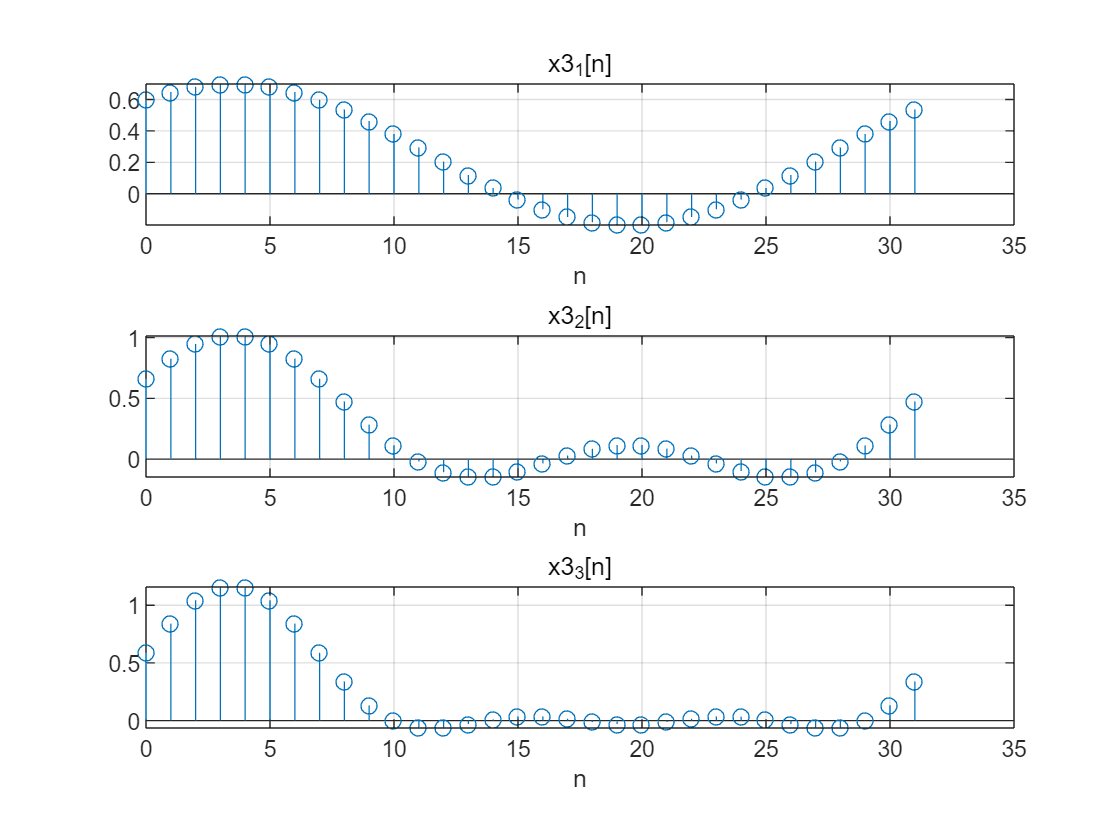

%得到了x3_all[n]

%输出所有的x3
figure;
subplot(3,1,1),stem(nx,real(x3_1)),title('x3_1[n]'),xlabel('n'),grid on;
subplot(3,1,2),stem(nx,real(x3_2)),title('x3_2[n]'),xlabel('n'),grid on;
subplot(3,1,3),stem(nx,real(x3_3)),title('x3_3[n]'),xlabel('n'),grid on;

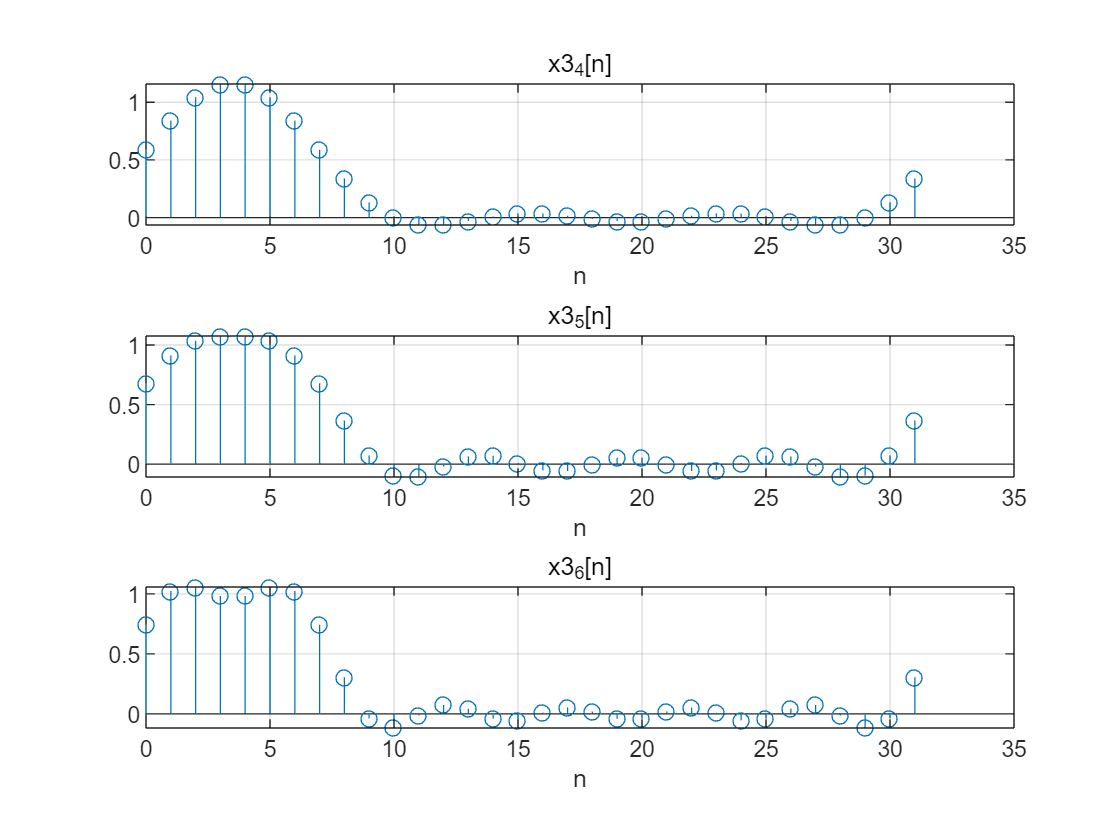

figure;
subplot(3,1,1),stem(nx,real(x3_4)),title('x3_4[n]'),xlabel('n'),grid on;
subplot(3,1,2),stem(nx,real(x3_5)),title('x3_5[n]'),xlabel('n'),grid on;
subplot(3,1,3),stem(nx,real(x3_6)),title('x3_6[n]'),xlabel('n'),grid on;

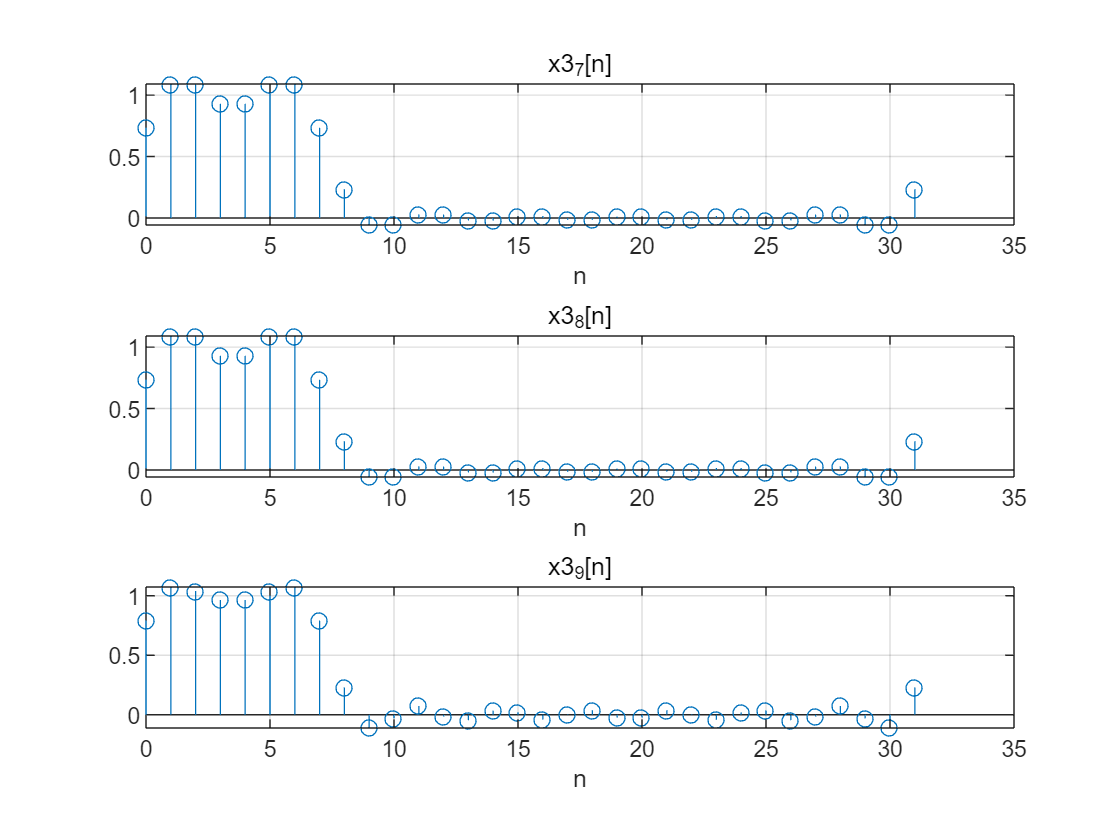

figure;
subplot(3,1,1),stem(nx,real(x3_7)),title('x3_7[n]'),xlabel('n'),grid on;
subplot(3,1,2),stem(nx,real(x3_8)),title('x3_8[n]'),xlabel('n'),grid on;
subplot(3,1,3),stem(nx,real(x3_9)),title('x3_9[n]'),xlabel('n'),grid on;

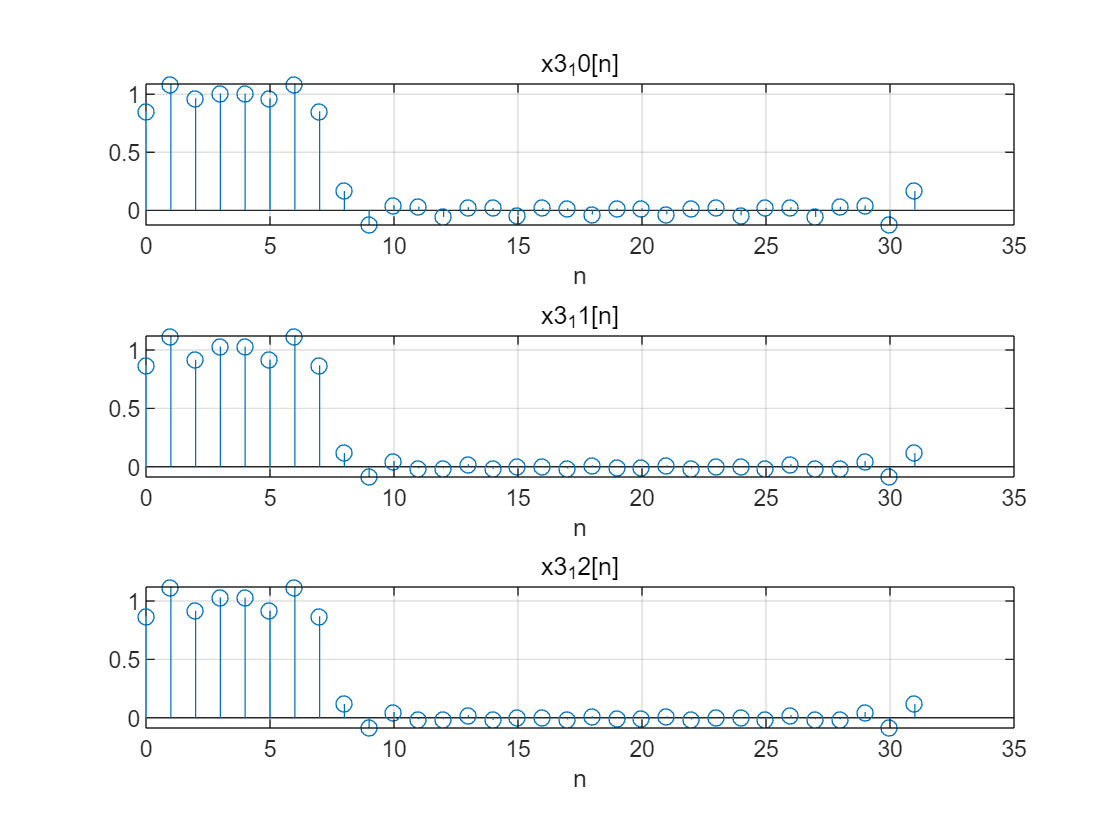

figure;
subplot(3,1,1),stem(nx,real(x3_10)),title('x3_10[n]'),xlabel('n'),grid on;
subplot(3,1,2),stem(nx,real(x3_11)),title('x3_11[n]'),xlabel('n'),grid on;
subplot(3,1,3),stem(nx,real(x3_12)),title('x3_12[n]'),xlabel('n'),grid on;

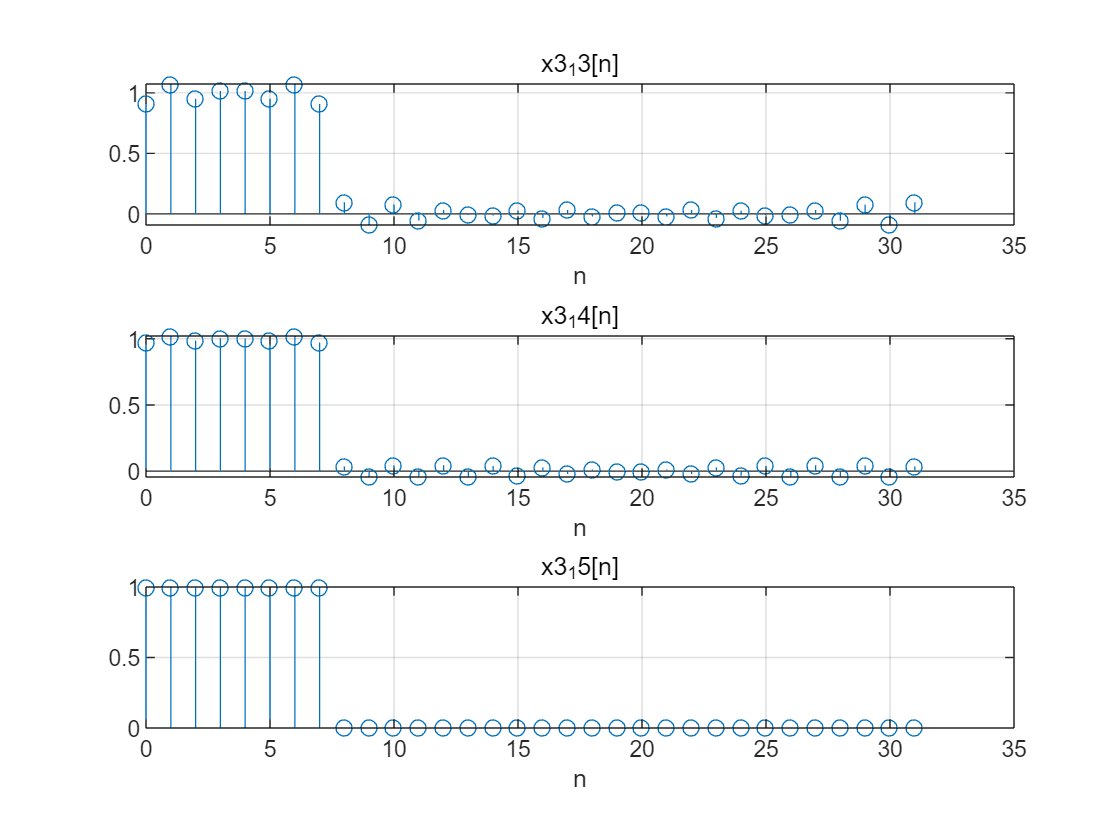

figure;
subplot(3,1,1),stem(nx,real(x3_13)),title('x3_13[n]'),xlabel('n'),grid on;
subplot(3,1,2),stem(nx,real(x3_14)),title('x3_14[n]'),xlabel('n'),grid on;
subplot(3,1,3),stem(nx,real(x3_15)),title('x3_15[n]'),xlabel('n'),grid on;

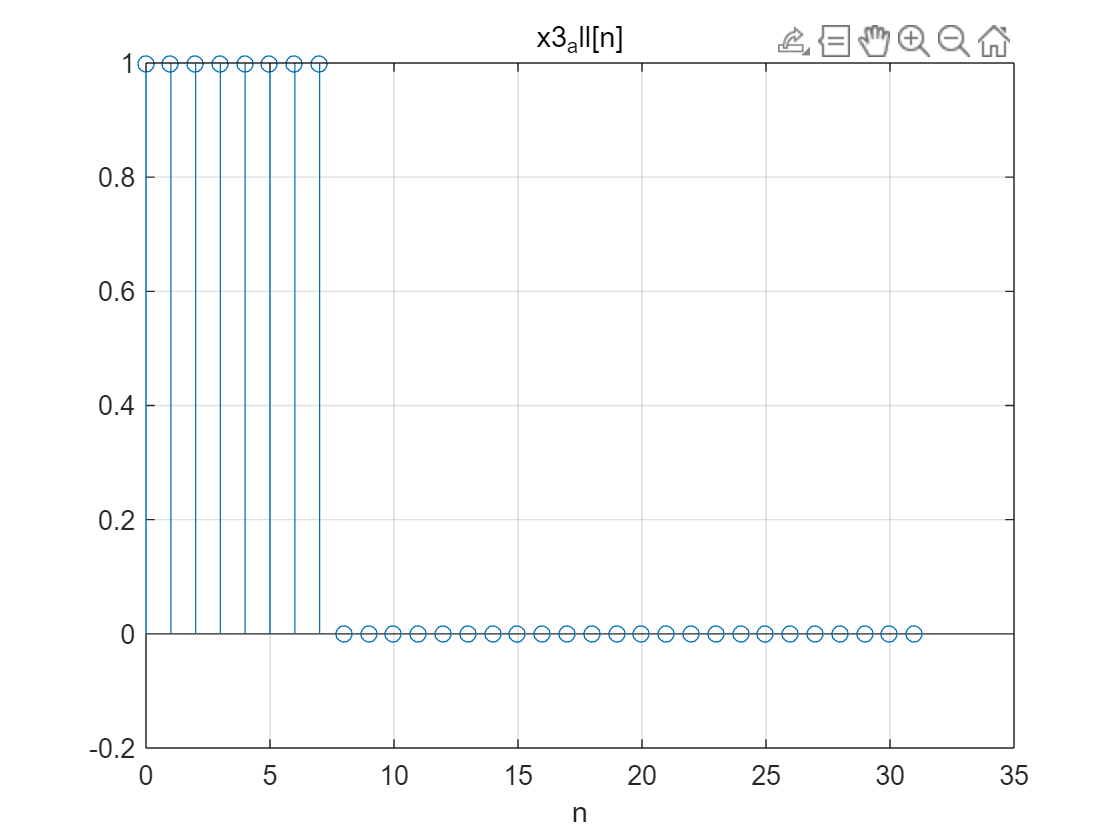

figure;
stem(nx,real(x3_all)),title('x3_all[n]'),xlabel('n'),grid on;

根据图像，可观察到，更多的谐波数量确实能够更加还原真实信号。

由于是离散信号，故不呈现吉布斯现象。

#### 3.5i 写一个函数，给定x，n_init，最后检验

根据题目要求检验

clc,clear,close all;
dtfs([1 2 3 4],0)

ans =    2.5000 + 0.0000i  -0.5000 + 0.5000i  -0.5000 - 0.0000i  -0.5000 - 0.5000i


dtfs([1 2 3 4],1)

ans =    2.5000 + 0.0000i   0.5000 + 0.5000i   0.5000 + 0.0000i   0.5000 - 0.5000i


dtfs([1 2 3 4],-1)

ans =    2.5000 + 0.0000i  -0.5000 - 0.5000i   0.5000 + 0.0000i  -0.5000 + 0.5000i


dtfs([2 3 4 1],0)

ans =    2.5000 + 0.0000i  -0.5000 - 0.5000i   0.5000 + 0.0000i  -0.5000 + 0.5000i


dtfs([ones(1,4) zeros(1,4)],0)

ans =    0.5000 + 0.0000i   0.1250 - 0.3018i  -0.0000 - 0.0000i   0.1250 - 0.0518i   0.0000 - 0.0000i   0.1250 + 0.0518i   0.0000 - 0.0000i   0.1250 + 0.3018i


dtfs([ones(1,4) zeros(1,4)],2)

ans =    0.5000 + 0.0000i  -0.3018 - 0.1250i   0.0000 + 0.0000i   0.0518 + 0.1250i   0.0000 - 0.0000i   0.0518 - 0.1250i  -0.0000 + 0.0000i  -0.3018 + 0.1250i


结果与示例相同。

#### 3.10a fft运算次数。

ak=sum(x[n]*exp(-j*k*2pi/N*n))/N，做n次乘法，将x[n]和exp(-j*k*2pi/N*n)相乘；做n-1次加法，每个循环末尾将新的运算结果加进sum中（sum初值为0），循环外，再做一次除法，计算出结果。

故需要n+1次复数乘除法，n-1次复数加减法。

#### 3.10b dtfs运算次数。

用etime记录运算时间。

clc,clear,close all;
N=[8 32 64 128 256];
dtfscomps=[];
for i=1:5
    x=(0.9).^[0:N(i)-1];
    f=@()dtfs(x,0);%fft运算
    dtfscomps=[dtfscomps timeit(f)];
end
dtfscomps

dtfscomps =     0.0000    0.0004    0.0014    0.0038    0.0124


计算出不同的n下dtfs所需时间。

#### 3.10c fft运算次数。

fftcomps=[];
for i=1:5
    x=(0.9).^[0:N(i)-1];
    f=@()fft(x,0);%fft运算
    fftcomps=[fftcomps timeit(f)];
end

fftcomps

fftcomps = 1.0e-06 *

    0.8586    0.8238    0.8132    0.7840    0.3255


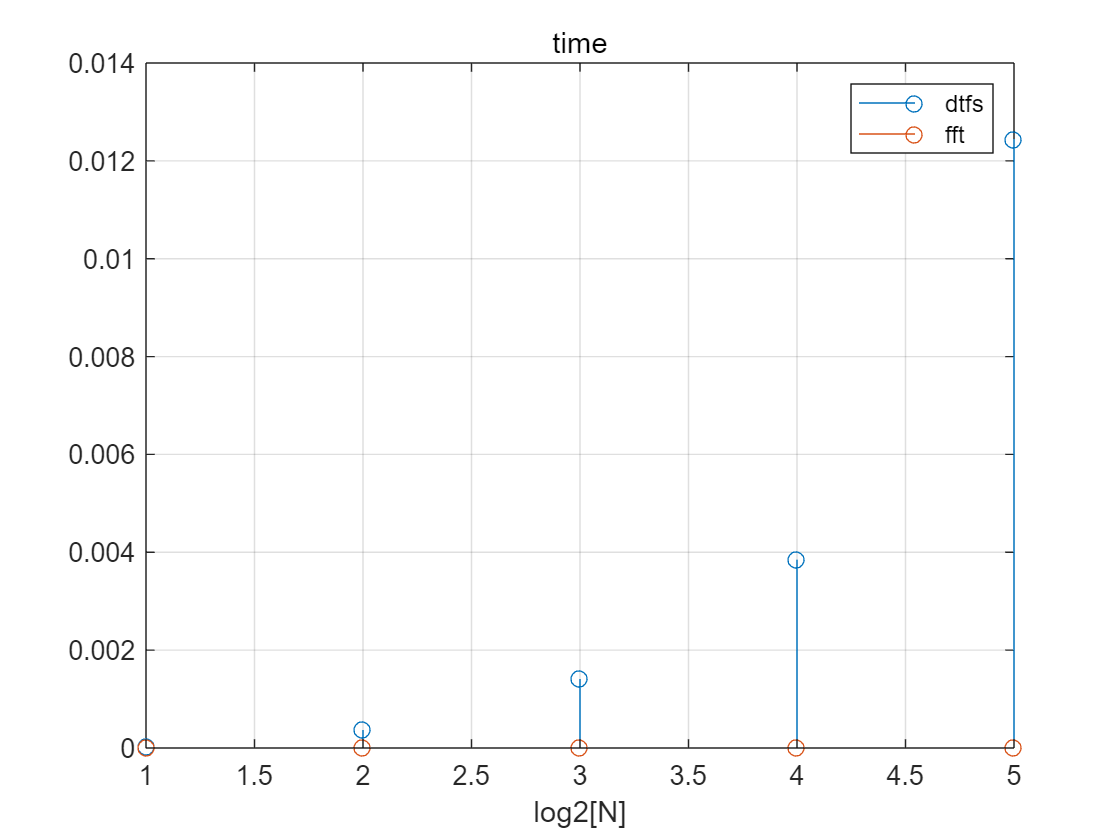

figure;
stem([1:5],dtfscomps),xlabel('log2[N]'),grid on;
hold on;
stem([1:5],fftcomps),xlabel('log2[N]'),grid on;
hold off;
legend('dtfs','fft'),title('time');

观察图像可知，fft方法较dtfs方法大幅度省时间。

#### 3.5i 函数部分

使用for循环遍历，带入公式，计算a

function a = dtfs(x,n_init)
    b=[];
    N=length(x);
    for i=n_init:N-1+n_init
        temp=0;
        for j=n_init:N-1+n_init
            h=x(j-n_init+1).*exp(-1i*2*pi*j*i/N);
            temp=temp+sum(h);
        end
        b=[b temp/N];
    end
    %得到了系数，但需调整至正确顺序
    if(n_init==0)
        a=b;
    end
    if(n_init>0)
        a=[b(end-n_init+1:end) b(1:end-n_init)];
    end
    if(n_init<0)
        a=[b(1-n_init:end) b(1:-n_init)];
    end
end